# Laplace Transformation

### Q1: Find the Laplace transform of $g\left(t\right)={\textrm{te}}^{-3t}$.

### 
$${\textrm{Sol}}^n :$$
 

#### The solution can be obtained by *translation and change of scale properties *of Laplace transformation. The first translation or shifting property: If $\textrm{L‹}\left\lbrace F\left(t\right)\right\rbrace =\int_0^{\infty } e^{-\textrm{st}} F\left(t\right)\textrm{dt}=f\left(s\right)$, then we have 

$\textrm{L‹}\left\lbrace e^{\textrm{at}} F\left(t\right)\right\rbrace =f\left(s-a\right)$.

#### The code of Laplace transformation for given function is below: 

clear all;

% define the function
syms t; 
g(t) = t * exp(-3*t);
lap = laplace(g); % Laplace transformation
fprintf('Laplace tranform: ');

Laplace tranform: 

disp(lap)

$$\frac{1}{{\left(s+3\right)}^{2}}$$

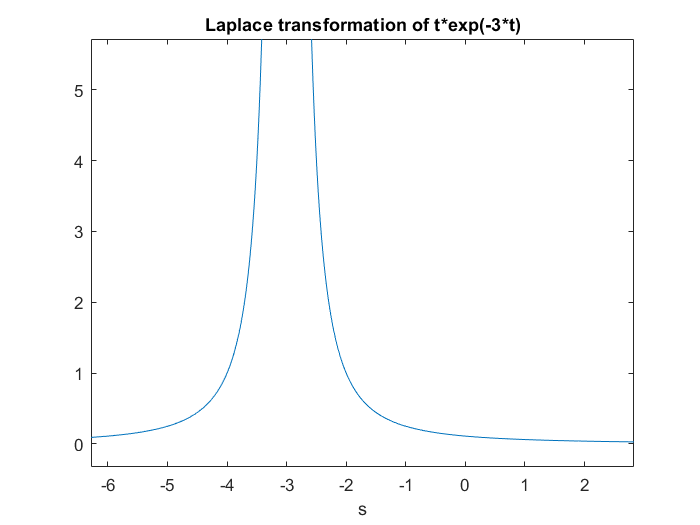


% ploting the solution
ezplot(lap);
title('Laplace transformation of t*exp(-3*t)');

### Q2: Find the Laplace transform of $f\left(t\right)=8\sin \left(5t\right)-e^{-t} \cos \left(2t\right)$

### 
$${\textrm{Sol}}^n :$$


#### The solution can be obtained by the *linear property *and *translation properties *of Laplace transformation respectively.

#### The first translation or shifting property: If $\textrm{L‹}\left\lbrace F\left(t\right)\right\rbrace =\int_0^{\infty } e^{-\textrm{st}} F\left(t\right)\textrm{dt}=f\left(s\right)$, then we have 

$\textrm{L‹}\left\lbrace e^{\textrm{at}} F\left(t\right)\right\rbrace =f\left(s-a\right)$.

#### and the linear property: If $c_1 \;$and $c_2$ are any constants while $F_1 \left(t\right)$and $F_1 \left(t\right)$are functions with Laplace transforms $f_1 \left(s\right)\;$and $f_2 \left(s\right)$respectively, then

$\textrm{L‹}\left\lbrace c_1 F_1 \left(t\right)+c_2 F_2 \left(t\right)\right\rbrace =c_1 \textrm{L‹}\left\lbrace F_1 \left(t\right)\right\rbrace +c_2 \textrm{L‹}\left\lbrace F_2 \left(t\right)\right\rbrace =c_1 f_1 \left(s\right)+c_2 f_2 \left(s\right)$.

#### The code of Laplace transformation for the given function is given below: 

clear all;

% define function
syms t;
f(t) = 8 * sin(5*t) - exp(-t) * cos(2*t);
lap = laplace(f); % Laplace transformation
fprintf('Laplace tranform: ');

Laplace tranform: 

disp(lap)

$$\frac{40}{s^{2}+25}-\frac{s+1}{{\left(s+1\right)}^{2}+4}$$

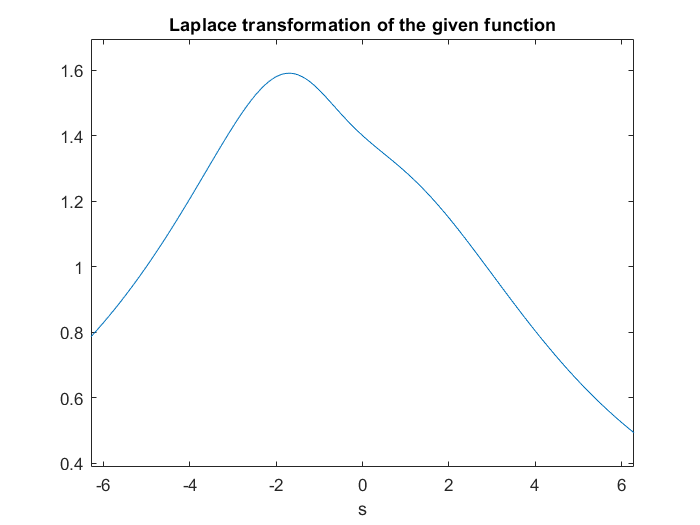


% ploting the solution
ezplot(lap);
title('Laplace transformation of the given function');

### Q3: What is the inverse Laplace transform of $f\left(s\right)=\;\frac{1}{s}-\frac{2s^2 +3}{s^2 +9}$.

### 
$${\textrm{Sol}}^n :$$


#### The inverse Laplace transform of this function can be obtained by *Linearity property *and then making a partial fraction of the second term. So, we get

$f\left(s\right)=\frac{1}{s}-\frac{2s^2 }{s^2 +9}+\frac{3}{s^2 +9}$.

#### Code of inverse Laplace for the given function is below: 

clear all;
syms s t;
f1(s) = (1/s);
f2(s) = (2*s^2 / (s^2+9));
f3(s) = (3 / (s^2+9));
ilf1 = ilaplace(f1);
ilf2 = ilaplace(f2);
ilf3 = ilaplace(f3);
fprintf('The inverse Laplace of f(s): ');

The inverse Laplace of f(s): 

f(t) = ilf1 + ilf2 + ilf3;
disp(f)

$$2\,\delta (t)-5\,\sin\left(3\,t\right)+1$$

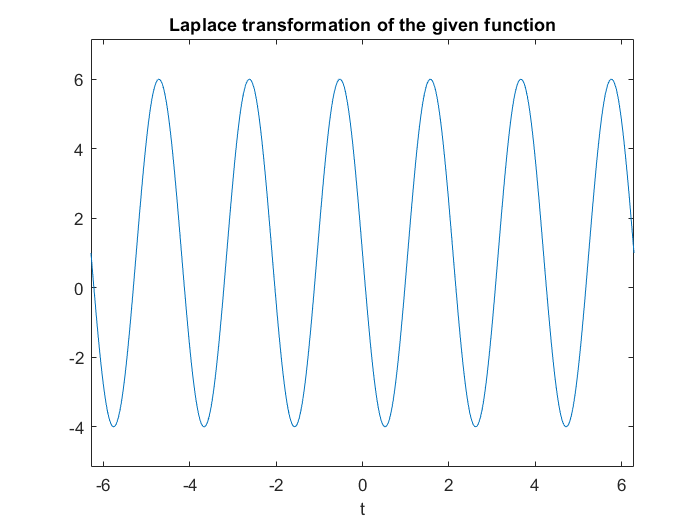


% ploting the solution
ezplot(f);
title('Laplace transformation of the given function');

### Q4: What is the inverse Laplace transform of $f\left(s\right)=\frac{s}{s^2 -49}-\frac{3}{s^2 -9}\ldotp$

#### 
$${\textrm{Sol}}^n :$$


#### The code of inverse Laplace transfor if the given function is below: 

clear all;

% define the function
syms s;
f(s) = (s / (s^2-49)) - (3 / (s^2 - 9));
ilf = ilaplace(f); % performing Laplace transformation
fprintf('The inverse Laplace of f(s): ');

The inverse Laplace of f(s): 

disp(ilf)

$$\frac{{\mathrm{e}}^{-3\,t}}{2}-\frac{{\mathrm{e}}^{3\,t}}{2}+\frac{{\mathrm{e}}^{-7\,t}}{2}+\frac{{\mathrm{e}}^{7\,t}}{2}$$

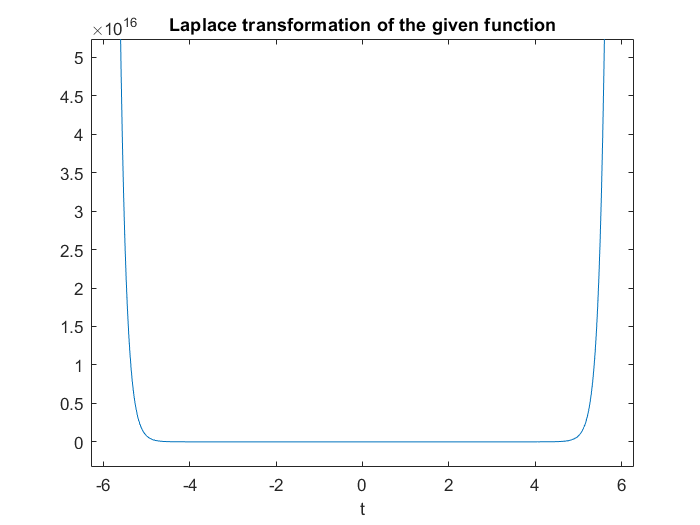


% ploting the solution
ezplot(ilf);
title('Laplace transformation of the given function');

### Q5: Solve the differential equation:


$$\frac{\textrm{dy}}{\textrm{dt}}+y=2U\left(t\right)$$


### where $U\left(t\right)$ is the heaviside function. Let all initial conditions be zero. What is the forced response?

#### 
$${\mathrm{Sol}}^n :$$


#### Given, $\frac{\mathrm{dy}}{\mathrm{dt}\;}+y=2U\left(t\right)$


$$\Rightarrow y^{\prime } +y=2U\left(t\right)$$



$$\Rightarrow {\mathrm{L‹}}^{-1} \;\left\lbrace y^{\prime } \right\rbrace +{\mathrm{L‹}}^{-1} \left\lbrace y\right\rbrace =2\;{\mathrm{L‹}}^{-1} \left\lbrace U_{a\left(\right.} \left(t\right)\right\rbrace$$



$$\Rightarrow \mathrm{sY}\left(s\right)+Y\left(s\right)=2\;\ldotp \frac{e^{-\mathrm{as}} }{s}$$



$$\Rightarrow Y\left(s\right)\left(s+1\right)=2\ldotp \frac{e^{-\mathrm{as}} }{s}$$



$$\Rightarrow Y\left(s\right)=\frac{2e^{-\mathrm{as}} }{s\left(s+1\right)}$$


#### $\Rightarrow Y\left(s\right)=2F\left(s\right)e^{-\mathrm{as}}$    where $F\left(s\right)=\frac{1}{s\left(s+1\right)}$


$$\Rightarrow {\mathrm{L‹}}^{-1} \left\lbrace Y\left(S\right)\right\rbrace ={\mathrm{L‹}}^{-1} \left\lbrace 2F\left(s\right)e^{-\mathrm{as}} \right\rbrace$$


#### Now the code for solving the following function Y(s) is: 

clear all;

% define the function 
syms s;
a = 1;
y(s) = (2*exp(-a*s)) / (s*(s+1));

% performing inverse Laplace tranform
lt = ilaplace(y);

fprintf('The solution: ');

The solution: 

disp(lt)

$$-2\,\mathrm{heaviside}\left(t-1\right)\,\left({\mathrm{e}}^{1-t}-1\right)$$

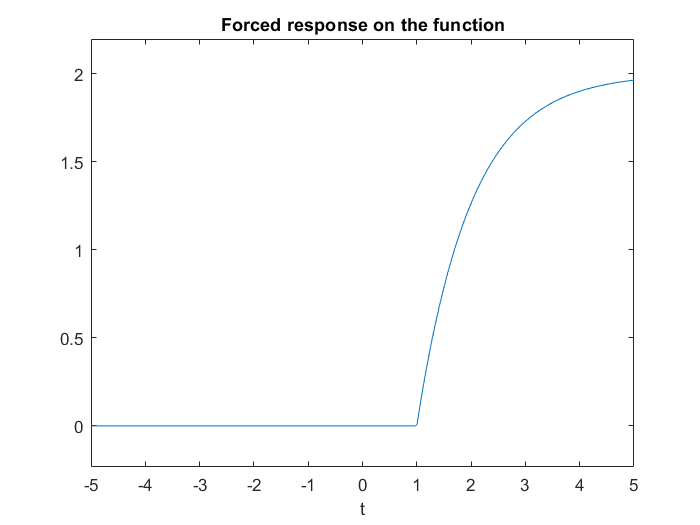


% ploting the solution
ezplot(lt, [-5 5]);
title('Forced response on the function');

# Fourier Transformation

### Q1: Find the fourier transfor of $x^2$.

#### 
$${\mathrm{Sol}}^n :$$


#### The code for the following problem is below: 

clear all;

% define the function
syms x;
f = x^2;

% perform fourier transform
ft = fourier(f);
fprintf('The Fourier transform of the f(x): ');

The Fourier transform of the f(x): 

disp(ft);

$$-2\,\pi \,\delta^{\prime \prime }(w)$$

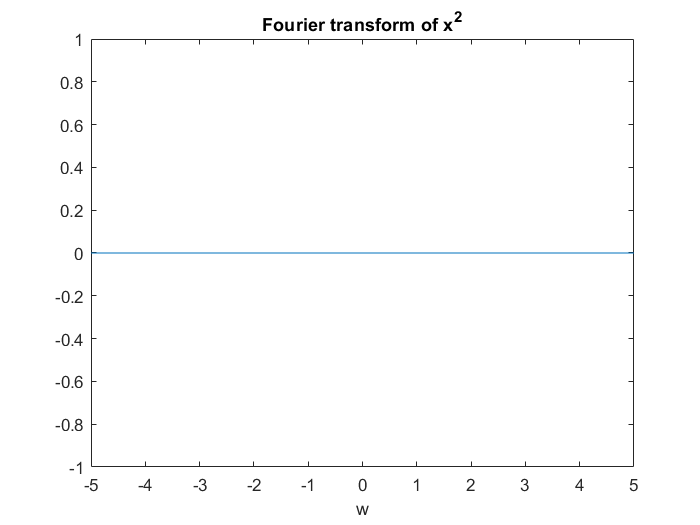


% plot the solution
ezplot(ft, [-5 5]);
title('Fourier transform of x^2');

### Q2: Find the fourier transfor of $x\;\mathrm{cos}\;x$.

#### 
$${\mathrm{Sol}}^n :$$


#### The code for the following problem is below:

clear all;

% define the function
syms x;
f = x * cos(x);

% performing fourier transform
ft = fourier(f);
fprintf('The Fourier transform of the f(x): ');

The Fourier transform of the f(x): 

disp(ft);

$$\pi \,\left(\delta^{\prime }(w-1)+\delta^{\prime }(w+1)\right)\,\mathrm{i}$$

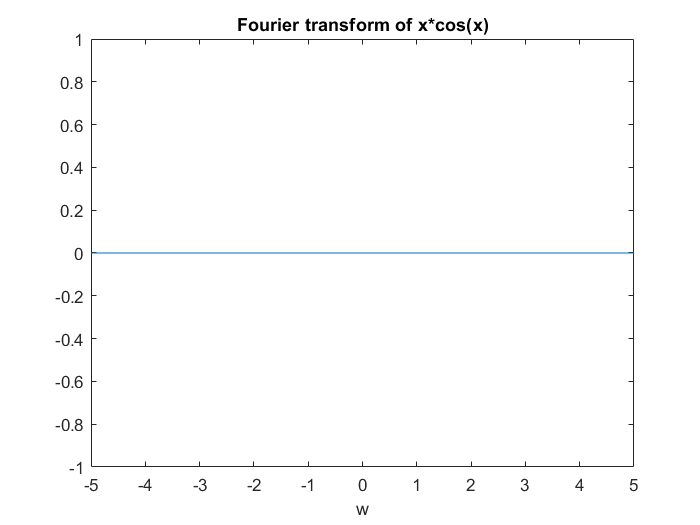


% ploting the solution
ezplot(ft, [-5 5]);
title('Fourier transform of x*cos(x)');

### Q3: Find the inverse Fourier transform of $\frac{1}{1+\iota \omega }\ldotp$

#### 
$${\mathrm{Sol}}^n :$$


#### The code for the solution of the given problem is below:

clear all;

% define the function
syms w;
f = 1 / (1 + i*w);

% performing inverse fourier transform
inv_f = ifourier(f);

fprintf('The solution is: ');

The solution is: 

disp(inv_f);

$$\frac{{\mathrm{e}}^{-x}\,\left(\mathrm{sign}\left(x\right)+1\right)}{2}$$

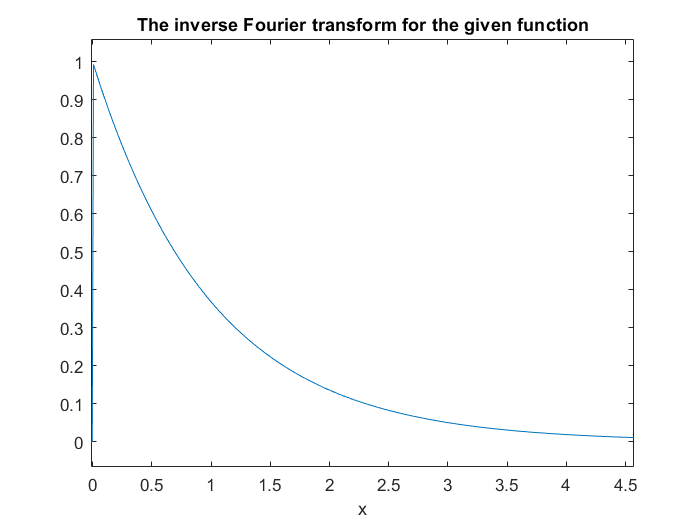


% ploting the solution
ezplot(inv_f);
title('The inverse Fourier transform for the given function');

### Q4: What is the fast Fourier transform of a = [2, 4, -1, 2].

#### 
$${\mathrm{Sol}}^n :$$


####  The code for the fast Fourier transform of a is below: 

clear all;

% define the signal
a = [2, 4, -1, 2];

% calculating the fft of the signal
ft = fft(a);

fprintf('The fast Fourier Transform of a: ');

The fast Fourier Transform of a: 

disp(ft);

   7.0000 + 0.0000i   3.0000 - 2.0000i  -5.0000 + 0.0000i   3.0000 + 2.0000i



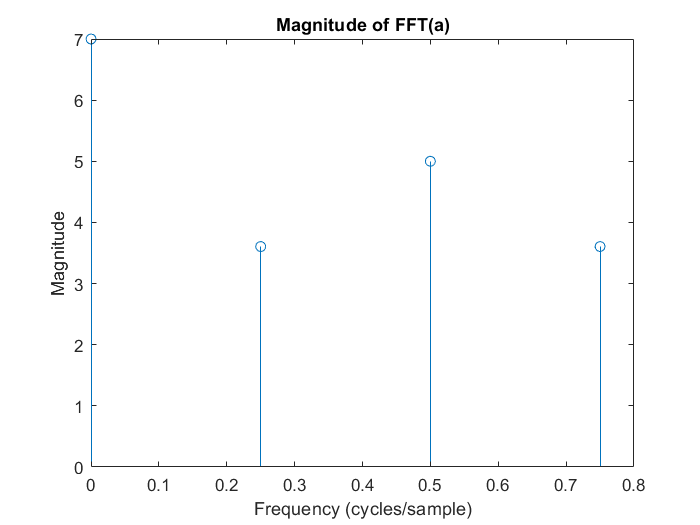


%ploting the figure
f = (0:length(ft)-1)/length(ft);
stem(f, abs(ft));
xlabel('Frequency (cycles/sample)');
ylabel('Magnitude');
title('Magnitude of FFT(a)');

### Q5: Let $x\left(t\right)=\mathrm{sin}\left(\pi t\right)+2\mathrm{sin}\left(4\pi t\right)$. Add some noise to the signal using randn(size(t)). What is the highest power content of the signal and at what frequency?

#### 
$${\mathrm{Sol}}^n :$$


#### The solution code is given below: 

clear all;

t = 0:0.01:10; % time matrix
x = sin(pi*t) + 2*sin(4*pi*t);
subplot(2, 2, 1); 
plot(x); title('main signal'); % ploting the main signal
x_noisy = x + randn(size(t)); % adding noise
subplot(2, 2, 3);
plot(1000*t(1:100), x_noisy(1:100)), xlabel('time(ms)'), title('Noisy singal');

% fast Fourier transform of the noisy signal
FT = fft(x_noisy, 512);
p = FT.*conj(FT)/512;
subplot(2, 2, 4);
plot(FT, p);

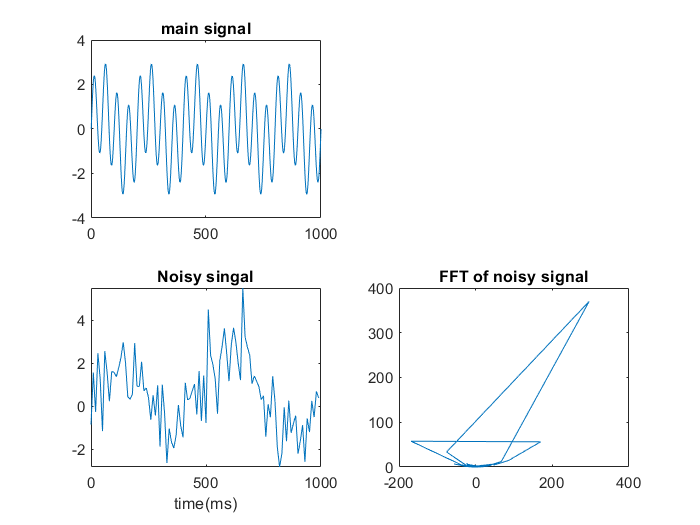

title('FFT of noisy signal');


% finding the highest value of power of the signal
[~, idx] = max(FT(1:end/2));
max_freq = (idx-1) / (length(FT)/2) * (1/0.001);
fprintf('The highest power signal is at %0.3f Hz\n', max_freq);

The highest power signal is at 39.063 Hz
